close all
clear all

## Ex 1

### a)

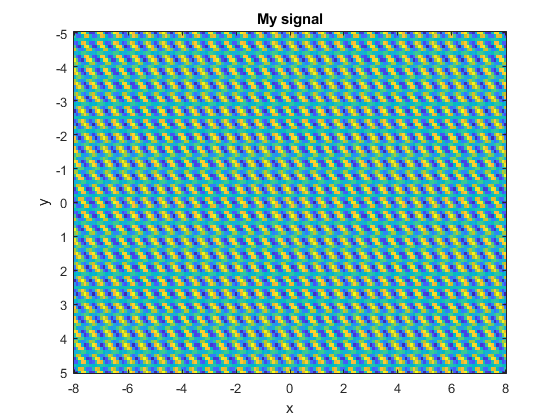

[x,y] = meshgrid(-8:0.1:8, -5:0.1:5);   %creamos una meshgrid con estos limites por cada eje
a = 13;
b= 17;
psi = a*cos(pi*(a/5)*y) .* cos(pi*(b/5)*(x-y));

%plot
figure(1)
imagesc(-8:0.1:8, -5:0.1:5, psi);
title('My signal')
xlabel('x')
ylabel('y')

#### transformada de fourier (apartado d)

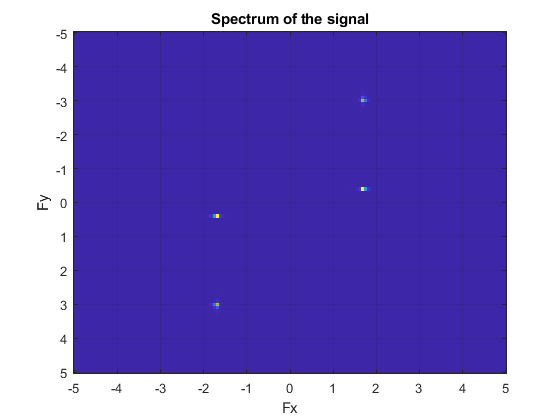

F = fft2(psi);
F = fftshift(F);        %sale en funcion de ciclo por imagen

[M,N] = size(psi);      %calculamentos la medida de psi 
%lo representamos en freq por unidad, lo dividimos por N-1 porque la señal
%pasa por el 0 y lo normalizamos muultiplicando por 10 ya que los pasos son
%de 0.1. Ya que 0.1*10 = 1 y lo estamos mostrando en freq por unidad.
fx = [-floor(N/2):floor(N/2)]/(N-1)*10;
fy = [-floor(M/2):floor(M/2)]/(M-1)*10;

%plot
figure(2)
imagesc(fx, fy, abs(F).^2)
title('Spectrum of the signal')
xlabel('Fx')
ylabel('Fy')
grid on  %hemos aplicado la grid para ver mejor donde son los valores

%en el eje y salen las frecuencias giradas ya que el eje va de negativo a
%positivo. 


### b)

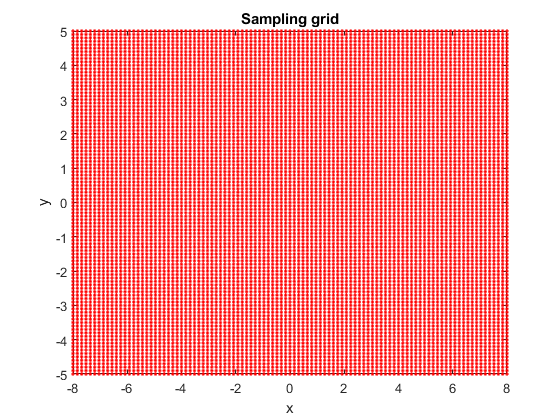

%representamos la lattice (Vn)
%V = [4/25 0; 0 1/10];
[x,y] = meshgrid(-8:4/25:8, -5:1/10:5);

figure(3)
plot(x(:), y(:),'.r');
title('Sampling grid')
xlabel('x')
ylabel('y')
xlim([-8, 8])
ylim([-5, 5])

### c)

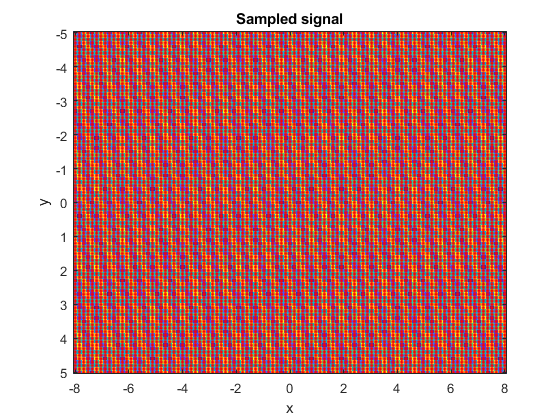

%representamos la samplng grid junto con la señal
figure(4)
psi = a*cos(pi*(a/5)*y) .* cos(pi*(b/5)*(x-y));
imagesc(-8:4/25:8, -5:1/10:5, psi);
title('Sampled signal')
xlabel('x')
ylabel('y')
hold on
plot(x(:), y(:),'.r');